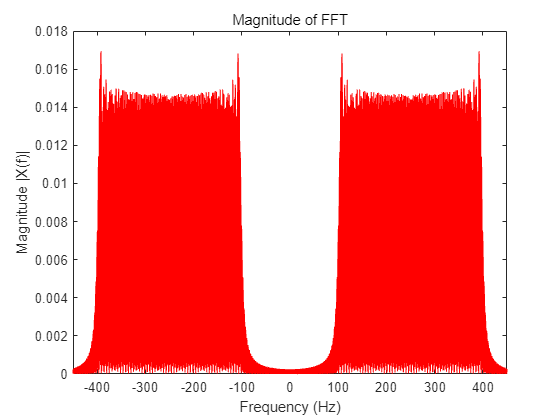

% parameters
fs=1000; %sampling frequency
t1=4; %% sweep time in seconds
t=0:1/fs:t1; %time base
tplot=[0:1/fs:t1 t1:1/fs:2*t1 2*t1:1/fs:3*t1]; % a time vector for three sweeps
f0=100;% starting frequency of the chirp
f1=400; %last frequency of the chirp 

t0=t(1); %% initialize sweep time
T=t1-t0; %% sweep time
k=(f1-f0)/T; %%rate of change of frequency

x1=cos(2*pi*(k/2*t+f0).*t);% 1st chirp
x2=cos(2*pi*(k/2*t+f0).*t);% 2nd chirp
x3=cos(2*pi*(k/2*t+f0).*t);% 3rd chirp
x=[x1 x2 x3]; % % concatenating all three chirps into one vector
%%
% %% 1 sec polt of chirp%%
% figure
% plot(tplot,x,'k');
% title(['Chirp Signal']);
% xlabel('Time(s)');
% ylabel('Amplitude');
% DFT of the chirp to show its bandwidth
L=length(x); % length of 3 sweeps
NFFT = 16384; % N- point DFT
X = fftshift(fft(x,NFFT)); % DFT  vector
f = fs*(-NFFT/2:NFFT/2-1)/NFFT; %Frequency Vector
figure
plot(f,abs(X)/(L),'r');
title('Magnitude of FFT');
xlabel('Frequency (Hz)')
ylabel('Magnitude |X(f)|');
xlim([-450 450]) % frequency axis limits

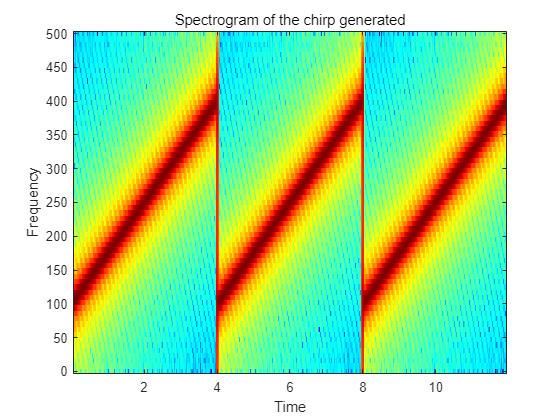

% spectrogram representation of the transmitted chirp
step=ceil(20*fs/1000);    %% one spectral slice every 20 ms
window=ceil(100*fs/1000); %% 100 ms data window
[S, fx, t] = specgram(x);
figure
specgram(x, 2^nextpow2(window), fs, window, window-step);
title(['Spectrogram of the chirp generated']);

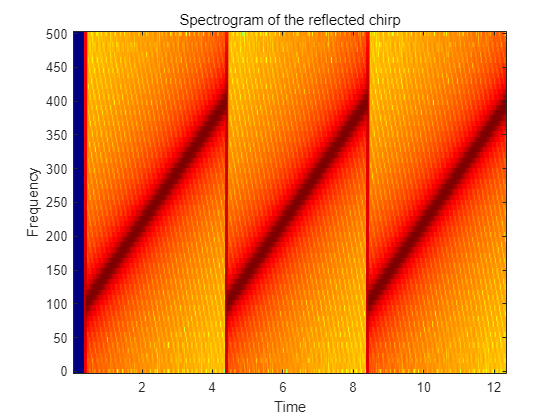

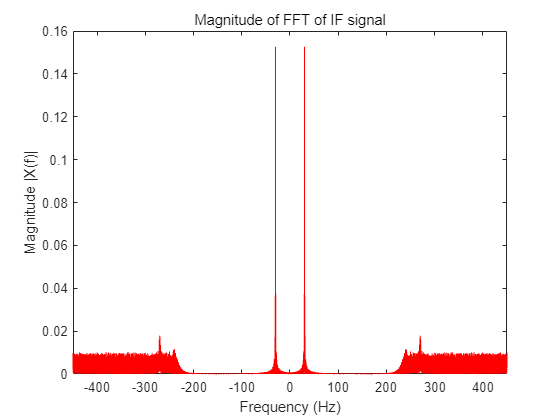

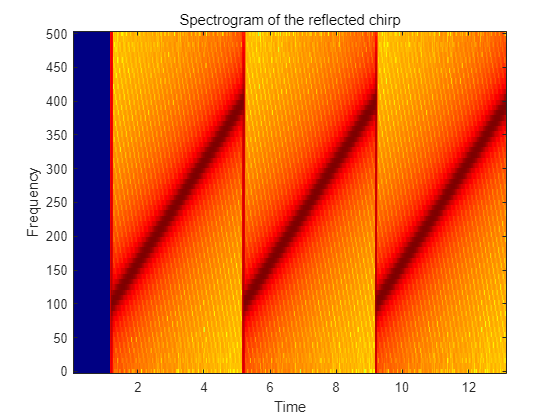

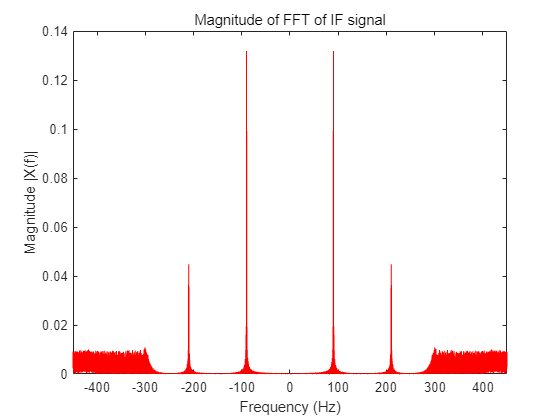

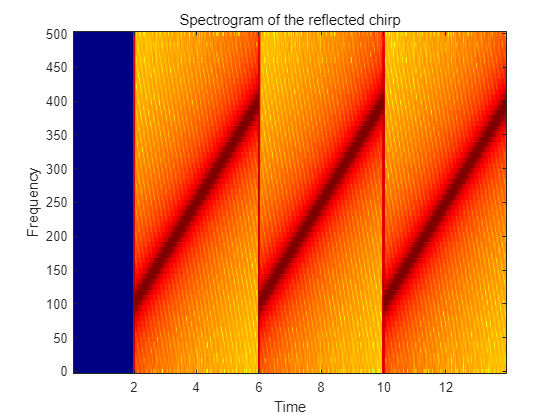

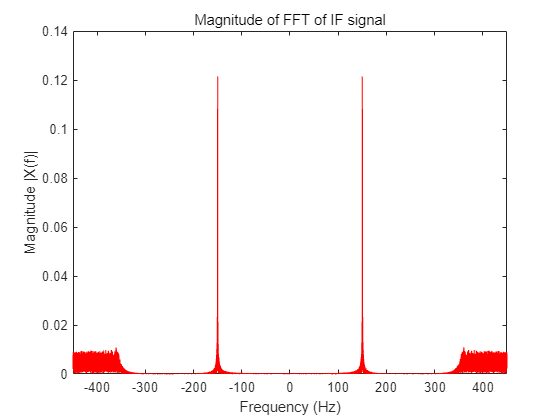

%%
%%reflections part
D=[400 1200 2000]; % modeling the delay of the 3 targets in milliseconds
for r = 1:3
    tq=8+(D(r)/1000);
    tref =[tplot 2*t1:1/fs:tq]; % time vector for each target
    Z= zeros(1,D(r)+1); % appending zeros to equal the size of generated  and reflected signal
    X_refl = [Z x]; % a model of received signals with delays as shown
%     figure
%     plot(tref,X_refl,'k');
%     title(['Reflected Chirp Signal']);
%     xlabel('Time(s)');
%     ylabel('Amplitude');
    % spectrogram for the reflected signal
    stepx=ceil(20*fs/1000);    %% one spectral slice every 20 ms
    windowx=ceil(100*fs/1000); %% 100 ms data window
    [Sx, fxx, tref] = specgram(X_refl);
    figure
    specgram(X_refl, 2^nextpow2(windowx), fs, windowx, windowx-stepx);
    title(['Spectrogram of the reflected chirp']);
    
    %%
    % IF signal (obtained by subtracting the recieved chirp from the sent one)
    chirp_gen = [x Z]; % gene
    X_IF= dechirp(X_refl',chirp_gen');
    % % DFT of the IF signal
    LL=length(X_IF');
    NFFT = 16384;
    XX = fftshift(fft(X_IF',NFFT));
    ff = fs*(-NFFT/2:NFFT/2-1)/NFFT; %Frequency Vector
    figure
    plot(ff,abs(XX)/(LL),'r');
    title('Magnitude of FFT of IF signal');
    xlabel('Frequency (Hz)')
    ylabel('Magnitude |X(f)|');
    xlim([-450 450])


end

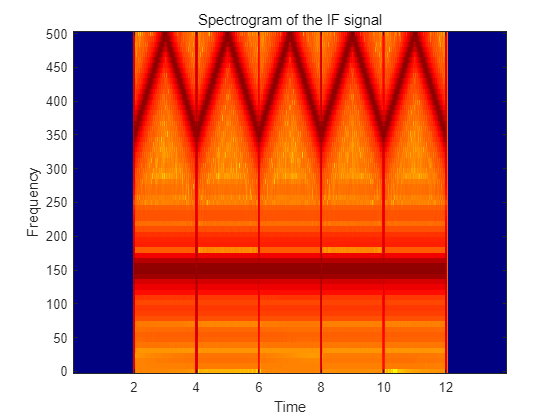


%%
% spectrogram for the reflected signal
stepi=ceil(20*fs/1000);    %% one spectral slice every 20 ms
windowi=ceil(100*fs/1000); %% 100 ms data window
[Si, fii, ti] = specgram(X_IF');
figure
specgram(X_IF', 2^nextpow2(windowi), fs, windowi, windowi-stepi);
title(['Spectrogram of the IF signal']);